clear all
close all

syms r z real                                           % coordinates
syms R_1n_1(n) R_1n_2(n) R_2n_2(n) Z_n_i1(n)  ...       % basis functions
        Z_n_i2(n) Lambda_k(k) N_k(n) Z_k_e(k) m_k(k)              
syms h a1 a2 d1 d2 m0 real positive                     % constants
syms n k j real integer                                     % counter index
assume(n >= 0)
assume(j >= 0)
assume(k >= 0)
syms C_1n_1(n) C_1n_2(n) C_2n_1(n) C_2n_2(n) B_k(k)     % unknown coefficients

N_num = 6;

% equation numbers refer to Chau & Yeung 2010 unless otherwise noted

%% setup analytical boundary value problem equations
% eq 4
lambda_n1(n) = n*pi/(h-d1);
lambda_n2(n) = n*pi/(h-d2);

% eq 5
phi_p_i1 = 1/(2*(h-d1)) * ((z+h)^2 - r^2/2);
phi_p_i2 = 1/(2*(h-d2)) * ((z+h)^2 - r^2/2);

% eq 7
R_1n_1(n) = piecewise(n==0, 1/2, n>=1, ...
                    besseli(0,lambda_n1(n)*r)/besseli(0,lambda_n1(n)*a2));
R_1n_2(n) = piecewise(n==0, 1/2, n>=1, ...
                    besseli(0,lambda_n2(n)*r)/besseli(0,lambda_n2(n)*a2));

% eq 8
R_2n_1(n) = sym(0);
R_2n_2(n) = piecewise(n==0, 1/2*log(r/a2), ...
    n>=1, besselk(0,lambda_n2(n)*r)/besselk(0,lambda_n2(n)*a2));

% eq 9
Z_n_i1(n) = piecewise(n==0, 1, n>=1, sqrt(2)*cos(lambda_n1(n)*(z+h)));
Z_n_i2(n) = piecewise(n==0, 1, n>=1, sqrt(2)*cos(lambda_n2(n)*(z+h)));

% eq 13
Lambda_k(k) = piecewise(k==0, besselh(0,1,m0*r)/besselh(0,1,m0*a2), ...
    k>=1, besselk(0,m_k(k)*r)/besselk(0,m_k(k)*a2));

% eq 2.34 in analytical methods book, also eq 16 in Seah and Yeung 2006 
N_k(k) = piecewise(k==0, 1/2*(1+sinh(2*m0*h)/(2*m0*h)), ...
                   k>=1, 1/2*(1+sin(2*m_k(k)*h)/(2*m_k(k)*h)) );

% eq 14
Z_k_e(k) = piecewise(k==0, 1/sqrt(N_k(k)) * cosh(m0 * (z+h)), ...
                     k>=1, 1/sqrt(N_k(k)) * cos(m_k(k) * (z+h)));


% coupling integrals
C_jn(j,n) = int(Z_n_i2(j) * Z_n_i1(n), z, -h, -d1);
C_jn2(j,n)= int(Z_n_i2(j) * Z_n_i1(n), z, -h, -d2);
C_nj(n,j) = int(Z_n_i2(n) * Z_n_i1(j), z, -h, -d1);
C_nj2(n,j)= int(Z_n_i2(n) * Z_n_i1(j), z, -h, -d2);
C_nk(n,k) = int(Z_n_i2(n) * Z_k_e(k),  z, -h, -d2);
C_nk2(n,k)= int(Z_n_i2(n) * Z_k_e(k),  z, -h, 0);

potential_small_small = true;
velocity_small_small = false;
velocity_large_small = true;

assert(~(velocity_large_small && velocity_small_small))

% potential matching
% equation 22 in old 1981 paper, applied to boundary 2-e
% 
dz_1 = h - d1;
dz_2 = h - d2;

if potential_small_small
    match_2e_potential = dz_2 * (C_1n_2(n)*subs(R_1n_2(n),r,a2) ...
        + C_2n_2(n)*subs(R_2n_2(n),r,a2)) + int( subs(phi_p_i2,r,a2) * Z_n_i2(n), z, -h, -d2) == ...
        symsum( B_k(k) * subs(Lambda_k,r,a2) * C_nk(n,k), k, 0, N_num); %good
else
    match_2e_potential = symsum((C_1n_2(n) * subs(R_1n_2(n),r,a2) + ...
        C_2n_2(n) * subs(R_2n_2(n),r,a2)) * C_nk(n,k),n,0,N_num)  == ...
        B_k(k) * subs(Lambda_k(k),r,a2) * h - ...
        int(subs(phi_p_i2,r,a2) * Z_k_e(k), z, -h, 0);
end

% equation 22 in old 1981 paper, applied to boundary 1-2

if potential_small_small
    match_12_potential = C_1n_1(n) * subs(R_1n_1(n),r,a1) * dz_1 == ...
        symsum(( C_1n_2(j) * subs(R_1n_2(j),r,a1) + ...
          C_2n_2(j) * subs(R_2n_2(j),r,a1) * C_jn(j,n) ),j,0,N_num) + ...
        int(subs(phi_p_i2,r,a1)*Z_n_i1(n) - subs(phi_p_i1,r,a1)*Z_n_i1(n), z, -h, -d1); %good
else
    match_12_potential = (C_1n_2(n) * subs(R_1n_2(n),r,a1) + C_2n_2(n) * subs(R_2n_2(n),r,a1)) * dz_2 == ...
        symsum(( C_1n_1(j) * subs(R_1n_1(j),r,a1) + ...
          C_2n_1(j) * subs(R_2n_1(j),r,a1) * C_nj2(n,j) ),j,0,N_num) + ...
        int(subs(phi_p_i1,r,a1)*Z_n_i2(n) - subs(phi_p_i2,r,a1)*Z_n_i2(n), z, -h, -d2);
end

% velocity matching
% equation 23 in old 1981 paper, applied to boundary 2-e
if velocity_large_small
    match_2e_velocity = (h) * (C_1n_2(n)*subs(diff(R_1n_2(n),r),r,a2) ...
        + C_2n_2(n)*subs(diff(R_2n_2(n),r),r,a2)) + int( subs(diff(phi_p_i2,r),r,a2) * Z_n_i2(n), z, -h, 0) == ...
        symsum( B_k(k) * subs(diff(Lambda_k,r),r,a2) * C_nk2(n,k), k, 0, N_num);
elseif velocity_small_small
    match_2e_velocity = dz_2 * (C_1n_2(n)*subs(diff(R_1n_2(n),r),r,a2) ...
        + C_2n_2(n)*subs(diff(R_2n_2(n),r),r,a2)) + int( subs(diff(phi_p_i2,r),r,a2) * Z_n_i2(n), z, -h, -d2) == ...
        symsum( B_k(k) * subs(diff(Lambda_k,r),r,a2) * C_nk(n,k), k, 0, N_num);
else
    match_2e_velocity = B_k(k) * subs(diff(Lambda_k(k), r), r, a2) * (h) == ...
        symsum((C_1n_2(n) * subs(diff(R_1n_2(n), r), r, a2) + ...
         C_2n_2(n) * subs(diff(R_2n_2(n), r), r, a2) ) * C_nk(n,k), n, 0, N_num) + ...
        int(subs(diff(phi_p_i2,r),r,a2) * Z_k_e(k), z, -h, -d2 ); %good
end

% equation 23 in old 1981 paper, applied to boundary 1-2
if velocity_large_small
    % use large region (-h to -d2) and multiply by Z_n_i1
     match_12_velocity = (h-d1) * ( C_1n_1(n) * subs(diff(R_1n_1(n), r), r, a1) + ...
     C_2n_1(n) * subs(diff(R_2n_1(n), r), r, a1) ) + int( subs(diff(phi_p_i1,r),r,a1) * Z_n_i1(n), z, -h, -d1 ) == ...
     symsum((C_1n_2(j) * subs(diff(R_1n_2(j), r), r, a1) + ...
     C_2n_2(j) * subs(diff(R_2n_2(j), r), r, a1) ) * C_jn2(j,n), j, 0, N_num) + ...
     int( subs(diff(phi_p_i2,r),r,a1) * Z_n_i1(n), z, -h, -d2 );
elseif velocity_small_small
    % use small region (-h to -d1) and multiply by Z_n_i1
    match_12_velocity = dz_1 * (C_1n_1(n) * subs( diff(R_1n_1(n),r), r,a1) + ...
        C_2n_1(n) * subs( diff(R_2n_1(n),r), r,a1) ) ==...
        symsum( (C_1n_2(j) * subs(diff(R_1n_2(j),r), r, a1) + ...
        C_2n_2(j) * subs(diff(R_2n_2(j),r), r, a1) ) * C_jn, j, 0, N_num) + ...
        int( subs(diff(phi_p_i2 - phi_p_i1,r),r,a1) * Z_n_i1(n), z, -h, -d1 );
else
    % use large region (-h to -d2) and multiply by Z_n_i2
    match_12_velocity = (h-d2) * ( C_1n_2(n) * subs(diff(R_1n_2(n), r), r, a1) + ...
     C_2n_2(n) * subs(diff(R_2n_2(n), r), r, a1) ) + int( subs(diff(phi_p_i2,r),r,a1) * Z_n_i2(n), z, -h, -d2 ) == ...
     symsum((C_1n_1(j) * subs(diff(R_1n_1(j), r), r, a1) + ...
     C_2n_1(j) * subs(diff(R_2n_1(j), r), r, a1) ) * C_nj(n,j), j, 0, N_num) + ...
     int( subs(diff(phi_p_i1,r),r,a1) * Z_n_i2(n), z, -h, -d1 );
end


%syms npos real integer positive
%assume(npos>=1)

% Aside: confirm which BCs are okay
% phi_h_i1_term1 = R_1n_1([0;n]) .* Z_n_i1([0;n]);
% phi_h_i1_term2 = R_2n_1([0;n]) .* Z_n_i1([0;n]);
% phi_h_i2_term1 = R_1n_2([0;n]) .* Z_n_i2([0;n]);
% phi_h_i2_term2 = R_2n_2([0;n]) .* Z_n_i2([0;n]);
% phi_e_k = Lambda_k([0; n]) .* Z_k_e([0; n]);
% 
% % BCs for region 1
% % seafloor
% BC1 = subs(diff(phi_h_i1_term1,z),z,-h) == 0;
% BC2 = subs(diff(phi_h_i1_term2,z),z,-h) == 0;
% BC3 = subs(diff(phi_p_i1,z),z,-h) == 0;
% % z velocity on body
% BC4 = subs(diff(phi_h_i1_term1,z),z,-d1) == 0;
% BC5 = subs(diff(phi_h_i1_term2,z),z,-d1) == 0;
% BC6 = subs(diff(phi_p_i1,z),z,-d1) == 1;
% 
% % BCs for region 2
% % seafloor
% BC7 = subs(diff(phi_h_i2_term1,z),z,-h) == 0;
% BC8 = subs(diff(phi_h_i2_term2,z),z,-h) == 0;
% BC9 = subs(diff(phi_p_i2,z),z,-h) == 0;
% % z velocity on body
% BC10 = subs(diff(phi_h_i2_term1,z),z,-d2) == 0;
% BC11 = subs(diff(phi_h_i2_term2,z),z,-d2) == 0;
% BC12 = subs(diff(phi_p_i2,z),z,-d2) == 1;
% % r velocity on body
% BC13 = subs(diff(phi_h_i2_term1,r),{r,z},{a1,(-d1-d2)/2}) == 0;
% BC14 = subs(diff(phi_h_i2_term2,r),{r,z},{a1,(-d1-d2)/2}) == 0;
% BC15 = subs(diff(phi_p_i2,r),{r,z},{a1,(-d1-d2)/2}) == 0;
% 
% % BCs for region e
% % seafloor
% BC16 = subs(diff(phi_e_k,z),z,-h) == 0;
% % r velocity on body
% BC17 = subs(diff(phi_e_k,r),{r,z},{a2,-d2/2}) == 0;
% % free surface
% BC18 = 0 == 1; % placeholder
% 
% BCs = [BC1; BC2; BC3; BC4; BC5; BC6; BC7; BC8; ...
%     BC9; BC10; BC11; BC12; BC13; BC14; BC15; BC16; BC17; BC18];
% BCs = subs(BCs, sin(sym(pi)*n),0);
% BCs = [([1 1 2 2 3 4 4 5 5 6 7 7 8 8 9 10 10 11 11 12 13 13 14 14 15 16 16 17 17 18]).' BCs];
% BCs = simplify(BCs)

% BC17_new = subs(BC17,n,0)
% 
% % try subbing in m_k to BC17 to see if it makes it = 0
% syms m_k_bc m_0_bc real
% eqn = m_k_bc * tan(m_k_bc) == -m_0_bc * h * tanh(m_0_bc * h);


% solve equation
% substitute in [0,npos] for count variables
N_vec = (0:N_num);

if velocity_small_small || velocity_large_small
    vel_var = n;
else
    vel_var = k;
end
if potential_small_small
    pot_var = n;
else
    pot_var = k;
end

eqns = [subs(match_12_potential,n,N_vec), subs(match_2e_potential,pot_var,N_vec), ...
        subs(match_12_velocity, n,N_vec), subs(match_2e_velocity,vel_var,N_vec)].';

unknowns = [C_1n_1(N_vec) C_1n_2(N_vec) C_2n_2(N_vec) B_k(N_vec)];
syms C_1n_1_const C_1n_2_const C_2n_2_const B_k_const [1 N_num+1]
unknowns_const = [C_1n_1_const C_1n_2_const C_2n_2_const B_k_const];
eqns = subs(eqns, unknowns, unknowns_const)

syms m_k_const [1 N_num] real positive
eqns = subs(eqns,m_k(1:N_num),m_k_const);
%eqns = subs(eqns,sin(sym(pi)*n),0);
%eqns = subs(eqns,cos(sym(pi)*n),(-1)^n);
%eqns_0 = eqns([1,3,5,7])
%eqns_n = eqns([2,4,6,8])


[A,b] = equationsToMatrix(eqns,unknowns_const)


% u = unique([A,b])
% u = u(u~=0)
% syms c [length(u) 1]
% Au = A
% bu = b
% for i=1:length(u)
%     Au(Au==u(i)) = c(i)
%     bu(bu==u(i)) = c(i)
% end


a1_num = .5;
a2_num = 1;
d1_num = .5;
d2_num = .25;
h_num = 1.05;
m0_num = 1;
% r_in = .75;
% z_in = -.75;


syms m_k_h
eqn = m_k_h * tan(m_k_h) == -m0_num * h_num * tanh(m0_num * h_num);
for k_num = 1:N_num
    m_k_num(k_num) = double(vpasolve(eqn, m_k_h, sym(pi)*[k_num-1/2, k_num]))/h_num;
end

symbs = [a1,a2,d1,d2,h,m0,m_k_const];
nums = [a1_num,a2_num,d1_num,d2_num,h_num,m0_num,m_k_num];
%nums = mat2cell([nums, m_k_num], 1, ones(size([nums, m_k_num])))

% for entry_i = 1:size(A,1)
%     for entry_j = 1:size(A,2)
%         entry_i
%         entry_j
%         A_num = subs(A(entry_i,entry_j),symbs,nums)
%     end
% end


%A(3,12)

A_num = double(subs(A, symbs,nums));
b_num = double(subs(b, symbs,nums));

cond(A_num)

ans = 2.1352e+16


x_unscaled = full(A_num\b_num);


for maxval = [1e5 5e4]
    rows_to_scale = any(abs(full(A_num))>maxval,2)
    
    A_num(rows_to_scale,:) = A_num(rows_to_scale,:) / 10;
    b_num(rows_to_scale) = b_num(rows_to_scale) / 10;
end

rows_to_scale = 28×1 logical array
   0
   0
   0
   0
   1
   0
   0
   0
   0
   0


rows_to_scale = 28×1 logical array
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0




cond(A_num)

ans = 3.5459e+14


x = full(A_num\b_num);


%xu = Au\bu
%x = subs(xu,c,u)

%coeffs = solve(eqns,unknowns_const);


% reconstruct piecewise symfuns
% B_n(n)    = piecewise(n==0, coeffs.B_k_const1,    n>=1, coeffs.B_k_const2);
% C_1n_1(n) = piecewise(n==0, coeffs.C_1n_1_const1, n>=1, coeffs.C_1n_1_const2);
% C_1n_2(n) = piecewise(n==0, coeffs.C_1n_2_const1, n>=1, coeffs.C_1n_2_const2);
% C_2n_2(n) = piecewise(n==0, coeffs.C_2n_2_const1, n>=1, coeffs.C_2n_2_const2);


% get potential field
% eq 6
phi_h_n_i1(n) = (C_1n_1(n) * R_1n_1(n) + C_2n_1(n) * R_2n_1(n)) * Z_n_i1(n);
phi_h_n_i2(n) = (C_1n_2(n) * R_1n_2(n) + C_2n_2(n) * R_2n_2(n)) * Z_n_i2(n);

% eq 12
phi_e_k(k) = B_k(k) .* Lambda_k(k) .* Z_k_e(k);

% subs n for npos
% phi_h_n_i1(n) = subs(phi_h_n_i1(n), npos, n);
% phi_h_n_i2(n) = subs(phi_h_n_i2(n), npos, n);
% phi_e_k(n)    = subs(phi_e_k(n),    npos, n);

% simplify
phi_h_n_i1(n) = simplify(phi_h_n_i1(n),'IgnoreAnalyticConstraints',true);
phi_h_n_i2(n) = simplify(phi_h_n_i2(n),'IgnoreAnalyticConstraints',true);
phi_e_k(k)    = simplify(phi_e_k(k),   'IgnoreAnalyticConstraints',true);


% % sum all N terms
syms N real positive integer
syms phi_i1(N) phi_i2(N) phi_e(N)
phi_i1(N) = phi_p_i1 + symsum(phi_h_n_i1, n, 0, N);
phi_i2(N) = phi_p_i2 + symsum(phi_h_n_i2, n, 0, N);
phi_e(N)  = symsum(phi_e_k, k, 0, N);

% subs m_k_const for m_k(n) - note that it might make more sense to start
% with m_k_const in the beginning so this is never necessary
phi_e(N) = subs(phi_e(N), m_k(k), m_k_const);

% 
% vars = symvar(phi_i1)

% matlabFunction(phi_i1,phi_i2,phi_e,'File','generated/phi','Vars',vars)
% this errors due to matlab symsum bug

% matlabFunction of each n term indiviudally due to matlab symsum bug
%vars_n = symvar(phi_h_n_i1)
%matlabFunction(phi_h_n_i1,phi_h_n_i2,phi_e_k,'File','generated/phi_n','Vars',vars_n)
%vars_p = symvar([phi_p_i1 phi_p_i2])
%matlabFunction(phi_p_i1,phi_p_i2,'File','generated/phi_p','Vars',vars_p)

% matlabFunction of entire potential
%syms phi_h_n_i1_fcn([n, a1, a2, d1, d2, h, m0, m_k_const, r, z]) phi_h_n_i2_fcn([n, a1, a2, d1, d2, h, m0, m_k_const, r, z]) ...
%    phi_e_k_fcn([n, a1, a2, d1, d2, h, m0, m_k_const, r, z]) N
%vars_cell = sym2cell(vars_n);
%[phi_h_n_i1_fcn, phi_h_n_i2_fcn, phi_e_k_fcn] = phi_n(vars_cell{:})


% try again
%N = 20;
%phi_i2 = phi_p_i2 + phi_h_n_i2(0) + symsum(phi_h_n_i2(npos),npos,1,N)

% get hydro coeffs from potential
% equation 28 in old 1981 paper
integrand = subs(r * phi_i2 * diff(phi_i2,z),z,-d2);
hydro_nondim = (h/a2)^3 * 2 * int(integrand,r,a1,a2)

$$hydro\_nondim(N) = \begin{array}{l} \frac{2\,h^{3}\,\int_{a_{1}}^{a_{2}}r\,\left(\left(\sum_{n=0}^{N}\left\{ \begin{array}{cl} 0 & \text{ if }n=0\\ \frac{\pi \,\sqrt{2}\,n\,\sin\left(\pi \,n\right)\,\sigma_{1}}{d_{2}-h} & \text{ if }1\leq n \end{array}\right.\right)+1\right)\,\left(\frac{\frac{r^{2}}{2}-{\left(d_{2}-h\right)}^{2}}{2\,d_{2}-2\,h}+\left(\sum_{n=0}^{N}\left\{ \begin{array}{cl} \frac{C_{\mathrm{1n},2}\left(0\right)}{2}-C_{\mathrm{2n},2}\left(0\right)\,\left(\frac{\log\left(a_{2}\right)}{2}-\frac{\log\left(r\right)}{2}\right) & \text{ if }n=0\\ \sqrt{2}\,\cos\left(\pi \,n\right)\,\sigma_{1} & \text{ if }1\leq n \end{array}\right.\right)\right)\mathrm{d}r}{{a_{2}}^{3}}\\ \mathrm{where}\\ \sigma_{1}=\frac{C_{\mathrm{1n},2}\left(n\right)\,I_{0}\left(\sigma_{2}\right)}{I_{0}\left(\sigma_{3}\right)}+\frac{C_{\mathrm{2n},2}\left(n\right)\,K_{0}\left(-\sigma_{2}\right)}{K_{0}\left(-\sigma_{3}\right)}\\ \sigma_{2}=\frac{\pi \,n\,r}{d_{2}-h}\\ \sigma_{3}=\frac{\pi \,a_{2}\,n}{d_{2}-h} \end{array}$$

hnd = simplify(hydro_nondim,50);

% plug in numbers
hnd = subs(hnd, [symbs N], [nums N_num]);
hnd = subs(hnd, unknowns, x');
hnd = double(hnd);

% hndInfDepth = limit(hnd,h,inf)
% matlabFunction(hydro_nondim,'File','generated/hydro_nondim','Vars',symvar(hydro_nondim))
% geom_vars = [a1,a2,d1,d2,h];
% J = jacobian(hydro_nondim,geom_vars)
% matlabFunction(J,'File','generated/derivatives','Vars',symvar(J))

%hydro_nondim = subs(hydro_nondim, sin(sym(pi)*npos),0);
%hydro_nondim = subs(hydro_nondim, cos(sym(pi)*npos), (-1)^npos)
%hydro_nondim = simplify(hydro_nondim)
%mu = real(hydro_nondim)
%lambda = imag(hydro_nondim)


% derivatives to geometric variables

% hydro_terms = [mu,lambda];
% J = jacobian(hydro_terms,geom_vars);
% J = J(n) % turn symfun into sym so I can index matrix elements
% spy(J)
% xticklabels({'','a_1','a_2','d_1','d_2','h'})
% yticklabels({'','\mu','\lambda'})

% clear all
% N_num = 3;
% a1_num = 5;
% a2_num = 10;
% d1_num = 5;
% d2_num = 2.5;
% h_num = 10;
% m0_num = 1;
% r_in = .75;
% z_in = -.75;
spatial_res = 50;
r_vec = linspace(2*a2_num/spatial_res,2*a2_num,spatial_res);
z_vec = linspace(-h_num,0,spatial_res);
[R,Z] = meshgrid(r_vec,z_vec);

var = {phi_i1,phi_i2,phi_e};
for i = 1:3
    var{i} = subs(var{i}, [symbs N], [nums N_num]);
    var{i} = subs(var{i}, [unknowns m_k(1:N_num)], [x' m_k_num]);
    var{i} = subs(var{i}, {r,z},{R,Z});
    var{i} = double(var{i})
end

var = 1×3 cell array
    {50×50 double}    {1×1 symfun}    {1×1 symfun}


var = 1×3 cell array
    {50×50 double}    {50×50 double}    {1×1 symfun}


var = 1×3 cell array
    {50×50 double}    {50×50 double}    {50×300 double}


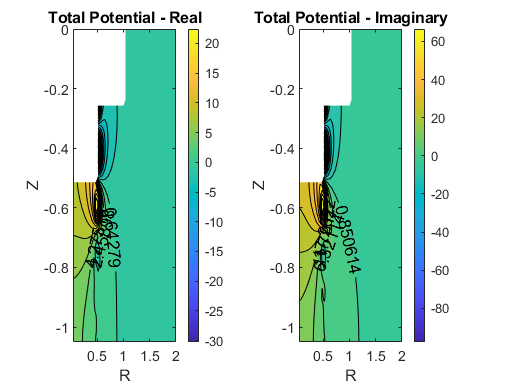

phi_i1_num = var{1};
phi_i2_num = var{2};
phi_e_num = var{3};

%[phi_i1,phi_i2,phi_e] = phi(N_in,a1_in,a2_in,d1_in,d2_in,h_in,m0_in,m_k_const_in,r_in,z_in)

% syms m_k_h
% eqn = m_k_h * tan(m_k_h) == -m0_num * h_num * tanh(m0_num * h_num);
% 
% [phi_h_n_i1_out,phi_h_n_i2_out,phi_e_k_out] = deal(zeros(1+N_num,spatial_res,spatial_res));
% for n_num = 0:N_num
%     i = n_num + 1;
%     if n_num >= 1
%         m_k_num = double(vpasolve(eqn, m_k_h, sym(pi)*[n_num-1/2, n_num]))/h_num;
%     else
%         m_k_num = NaN;
%     end
%     [phi_h_n_i1_out(i,:,:), phi_h_n_i2_out(i,:,:), phi_e_k_out(i,:,:)] = phi_n(...
%         n_num,a1_num,a2_num,d1_num,d2_num,h_num,m0_num,m_k_num,R,Z);
% end
% [phi_p_i1_out,phi_p_i2_out] = phi_p(d1_num,d2_num,h_num,R,Z);
% phi1 = phi_p_i1_out + sum(phi_h_n_i1_out);
% phi2 = phi_p_i2_out + sum(phi_h_n_i2_out);
% phie = sum(phi_e_k_out);

% assemble total phi based on phi in each region
regione = R > a2_num;
region1 = R < a1_num & Z < -d1_num;
region2 = R > a1_num & R <= a2_num & Z < -d2_num;

phi = NaN(size(R));
phi(region1) = phi_i1_num(region1);
phi(region2) = phi_i2_num(region2);
phi(regione) = phi_e_num(regione);

% phiH = NaN(size(R));
% phiH(region1) = phi1h(region1);
% phiH(region2) = phi2h(region2);
% 
% phiP = NaN(size(R));
% phiP(region1) = phi1p(region1);
% phiP(region2) = phi2p(region2);
% 
% v_r = NaN(size(R));
% v_r(region1) = v1r(region1);
% v_r(region2) = v2r(region2);
% v_r(regione) = ver(regione);
% 
% v_z = NaN(size(R));
% v_z(region1) = v1z(region1);
% v_z(region2) = v2z(region2);
% v_z(regione) = vez(regione);

plot_phi = true;
if plot_phi
    region_body = ~region1 & ~region2 & ~regione;
    plot_potential(phi,R,Z,region_body,'Total Potential');
    if potential_small_small
        phi_region = 'small-small';
    else 
        phi_region ='large-large';
    end
    if velocity_small_small
        vel_region = 'small-small';
    elseif velocity_large_small
        vel_region = 'large-small';
    else
        vel_region = 'large-large';
    end

    fname = [char(datetime('now','Format','yyyy-MM-dd h-mm a')) ', N=' num2str(N_num) ...
        ', phi = ' phi_region ', vel = ' vel_region];
    folder = ['dev' filesep 'MEEM_figs' filesep fname];
    savefig(folder)
%     plot_potential(phiH,R,Z,region_body,'Homogeneous Potential');
%     plot_potential(phiP,R,Z,region_body,'Particular Potential');
%     plot_potential(v_r,R,Z,region_body,'Radial Velocity')
%     plot_potential(v_z,R,Z,region_body,'Vertical Velocity')
%     plot_velocity(real(v_r),real(v_z),R,Z);
end

function [] = plot_potential(phi,R,Z,region_body,name)
    figure
    minphi = min(real(phi),[],'all');
    maxphi = max(real(phi),[],'all');

    num_levels = 30;
    if minphi<0
        levels = linspace(minphi,maxphi,num_levels);%[-logspace(log10(-minphi),0,num_levels/2), logspace(0,log10(maxphi),num_levels/2)];
        %levels = sort([levels, 135:145]);
    else
        levels = linspace(minphi,maxphi,num_levels);%[logspace(log10(minphi),log10(maxphi),num_levels)];
    end
    subplot 121
    [c,h_fig] = contourf(R,Z,real(phi),levels);
    clabel(c,h_fig)
    xlabel('R')
    ylabel('Z')
    title([name ' - Real'])
    colorbar;
    %set(gca,'ColorScale','log')
    
    imag_phi = imag(phi);
    if numel(unique(imag_phi)) > 1
        imag_phi(region_body) = NaN;
        subplot 122
        [c,h_fig] = contourf(R,Z,imag_phi,num_levels);
        clabel(c,h_fig)
        xlabel('R')
        ylabel('Z')
        title([name ' - Imaginary'])
        colorbar
    end
end
